clc; close all;
k = 4;
d = 30;
n = 5;
m = 1e6;

hmm_options.epsilon = 1/10;
hmm_options.method = "random";
hmm_options.distribution = 'Normal';

cpd_options.maxIter = 2500;
cpd_options.tol = 1e-14;
cpd_options.th_relerr = 1e-7;
cpd_options.epsilon = 1/10;

alpha = 0.05;
rho = 0.85;

[T, Os, pi, ~, ~] = generateHMM(k, d, n, hmm_options);

T_hats = cell(n,1);
O_hats = cell(n,1);

P3 = cell(n,1);
W = cell(n,1);
P_True = cell(n, 1);
[seq, states] = generate_multivariate_hmm_sequence(T, Os, pi, m);

for i = 1:n
    U = {};
    U{1} = (Os{i} * diag(pi) * T' / inv(diag(T * pi')));
    U{2} = Os{i};
    U{3} = (Os{i} * T);
    P_True{i} = cpdgen(U)./sum(cpdgen(U), 'all');

    [P3{i}, output] = ProbabilityTensorGenerate(seq(i, :), 3, d);
    P3{i} = P3{i} + eps;
    % W{i} = output.WeightMat + ones(d, d, d);
    % P3{i} = laplacian_smoothing_mle(P3{i}, 1e6);
end


cpd_options.True_T = T;
cpd_options.True_Os = Os;
cpd_options.True_Ps = P_True;

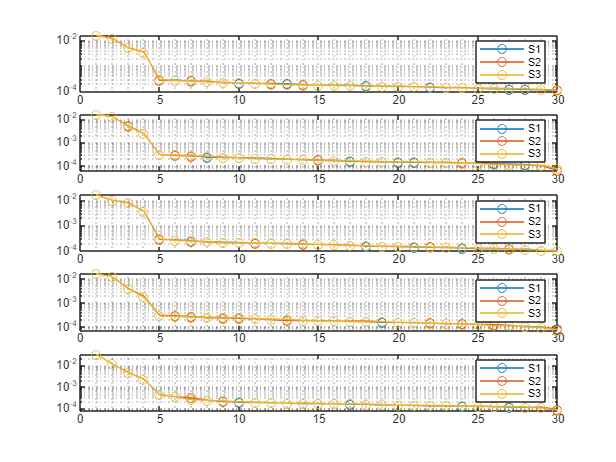




figure()
for i = 1:n
    P = P3{i};
    T1 = mode_n_matricization(P, 1);
    T2 = mode_n_matricization(P, 2);
    T3 = mode_n_matricization(P, 3);
    
    [~,S1,~] = svd(T1);
    [~,S2,~] = svd(T2);
    [~,S3,~] = svd(T3);
    
    subplot(n, 1, i);
    semilogy(nonzeros(S1), '-o'); hold on;
    semilogy(nonzeros(S2), '-o'); hold on;
    semilogy(nonzeros(S3), '-o'); hold on;
    grid minor; legend('S1','S2', 'S3')

end



for i = 1:n
    [C,U1,U2,U3] = mlsvd_3d(P3{i});
    U1t = U1(:, 1:k);
    U2t = U2(:, 1:k);
    U3t = U3(:, 1:k);
    Ct = C(1:k, 1:k, 1:k);
    P3{i} = rec_mlsvd_3d(Ct,U1t,U2t,U3t);
end

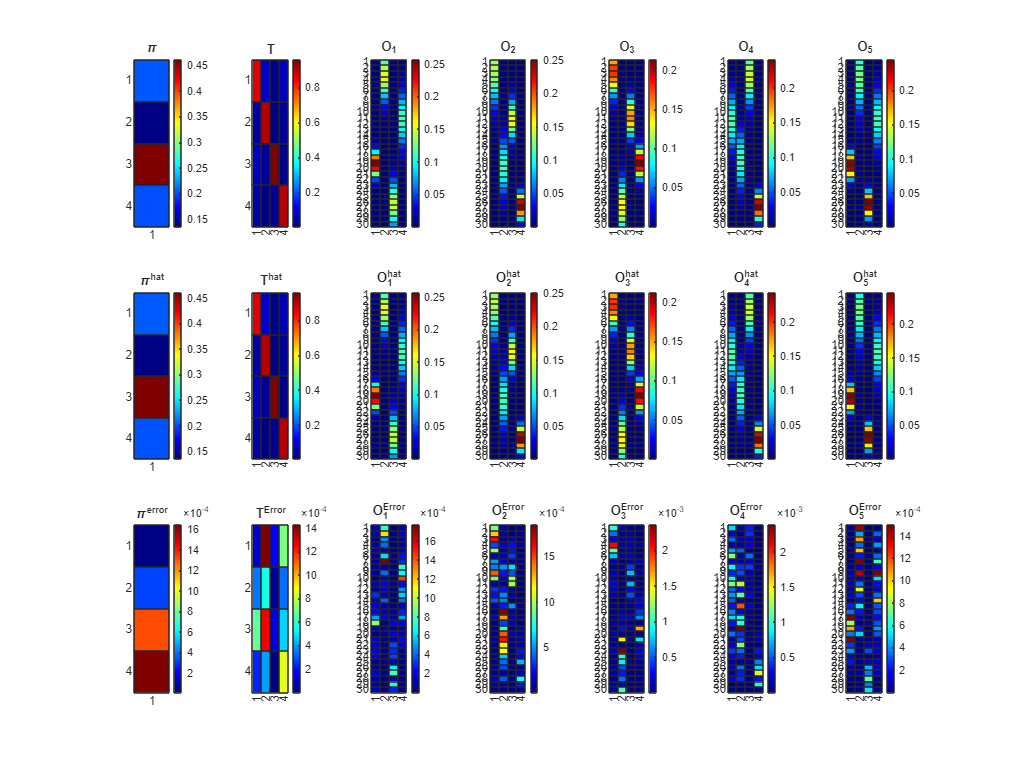

ans = 0.0085



% [T_hat, O_hats, pi_hat, output] = multivariate_coupled_cpd_4(P3, W, k, d, n, alpha, rho, cpd_options);
[T_hat, O_hats, pi_hat, output] = multivariate_coupled_cpd_2(P3, k, d, n, alpha, rho, cpd_options);
[T_hat, O_hats, pi_hat] = remove_hmm_permutation_transition(T, T_hat, O_hats, pi_hat);

HMMError(T, Os, T_hat, O_hats, true)

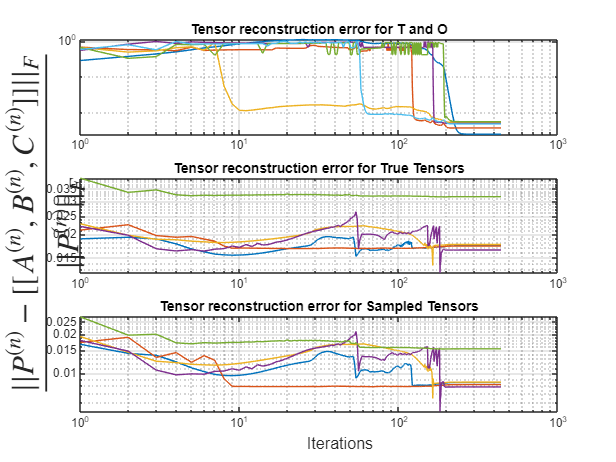


fig = figure();

subplot(3,1,1);
loglog(1:length(output.Trec), output.Trec, 1:length(output.Orec), output.Orec');
title('Tensor reconstruction error for T and O');
grid on;

subplot(3,1,2);
loglog(output.Prec');
title('Tensor reconstruction error for True Tensors');
grid on;

subplot(3, 1, 3);
loglog(output.recerr')
title("Tensor reconstruction error for Sampled Tensors")
% legendLabels = arrayfun(@(i) sprintf('Tensor $$ P^{(%d)}$$', i), 1:n, 'UniformOutput', false);
% legend(legendLabels, 'Interpreter', 'latex', 'FontSize',10);
grid on;

han=axes(fig,'visible','off'); 
han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,"$\frac{||P^{(n)} - [[A^{(n)} , B^{(n)} , C^{(n)} ]]||_F}{||P^{(n)}||_F}$", "Interpreter","latex", "FontSize",21, 'FontWeight','bold');
xlabel(han,'Iterations');